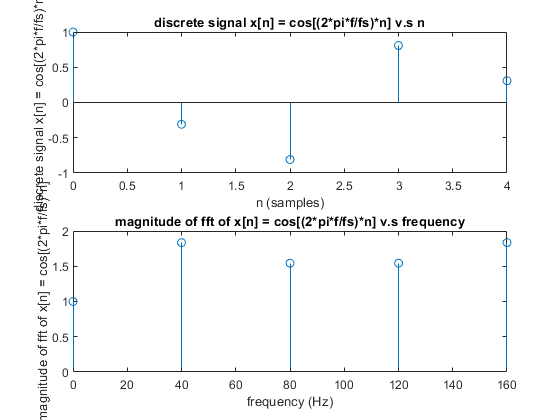

fs = 200;
f = 60;
N = 5;
n = 0:N-1;
x = cos((2*pi*f/fs)*n);
figure()
subplot(2,1,1)
stem(n,x)
title("discrete signal x[n] = cos[(2*pi*f/fs)*n] v.s n")
ylabel("discrete signal x[n] = cos[(2*pi*f/fs)*n]")
xlabel("n (samples)")

X = fft(x);
absX = abs(X);
r1 = (0:N-1)*(fs/N);
subplot(2,1,2)
stem(r1, absX)
title("magnitude of fft of x[n] = cos[(2*pi*f/fs)*n] v.s frequency")
ylabel("magnitude of fft of x[n] = cos[(2*pi*f/fs)*n]")
xlabel("frequency (Hz)")

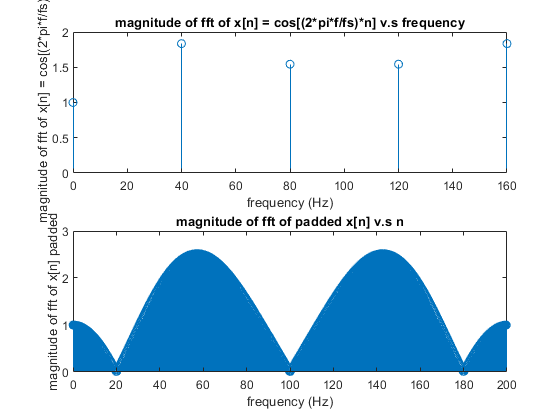


%
figure()
subplot(2,1,1)
stem(r1, absX)
title("magnitude of fft of x[n] = cos[(2*pi*f/fs)*n] v.s frequency")
ylabel("magnitude of fft of x[n] = cos[(2*pi*f/fs)*n]")
xlabel("frequency (Hz)")

N2 = N^4;
n2 = 0:N2 - 1;
x_pad = zeros(1, N2);
x_pad(1:N) = x(1:N);
X_pad = fft(x_pad);
r2 = (0:N2-1)*(fs/N2);
absX_pad = abs(X_pad);
subplot(2,1,2)
stem(r2,absX_pad)
title("magnitude of fft of padded x[n] v.s n")
ylabel("magnitude of fft of x[n] padded")
xlabel("frequency (Hz)")


max(absX)

ans = 1.8352

max(absX_pad)

ans = 2.5180